## Read


bag = rosbag('Tests_9.10\pt 9\robot_motion_pt_9_1.bag');

bSel = select(bag,'Topic','/tool_link_ee_pose')

bSel =   BagSelection with properties:

           FilePath: 'C:\Users\shrut\OneDrive\Documents\MATLAB\Tests_9.10\pt 9\robot_motion_pt_9_1.bag'
          StartTime: 1.6969e+09
            EndTime: 1.6969e+09
        NumMessages: 1244
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1244×4 table]


% 
msgStructs = readMessages(bSel,'DataFormat','struct');
X = cellfun(@(m) (m.Transform.Translation.X),msgStructs);
Y = cellfun(@(m) (m.Transform.Translation.Y),msgStructs);
Z = cellfun(@(m) (m.Transform.Translation.Z),msgStructs);
robot_positions = [X Y Z]

robot_positions =    -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551
   -0.6353   -0.0063    0.2551


X = cellfun(@(m) (m.Transform.Rotation.X),msgStructs);
Y = cellfun(@(m) (m.Transform.Rotation.Y),msgStructs);
Z = cellfun(@(m) (m.Transform.Rotation.Z),msgStructs);
W = cellfun(@(m) (m.Transform.Rotation.W),msgStructs);
robot_orintations_quaternion = [W X Y Z]

robot_orintations_quaternion =     0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115
    0.0045    0.7122    0.7018    0.0115


robot_orientation_euler_deg = quat2eul(robot_orintations_quaternion,'ZYX')*180/pi;
n = length(X);
time_init = double(msgStructs{1,1}.Header.Stamp.Sec);
time_final = double(msgStructs{n,1}.Header.Stamp.Sec);
time = linspace(0,time_final-time_init,n)

time =          0    0.0442    0.0885    0.1327    0.1770    0.2212    0.2655    0.3097    0.3540    0.3982    0.4425    0.4867    0.5310    0.5752    0.6195    0.6637    0.7080    0.7522    0.7965    0.8407    0.8850    0.9292    0.9735    1.0177    1.0619    1.1062    1.1504    1.1947    1.2389    1.2832    1.3274    1.3717    1.4159    1.4602    1.5044    1.5487    1.5929    1.6372    1.6814    1.7257    1.7699    1.8142    1.8584    1.9027    1.9469    1.9912    2.0354    2.0796    2.1239    2.1681


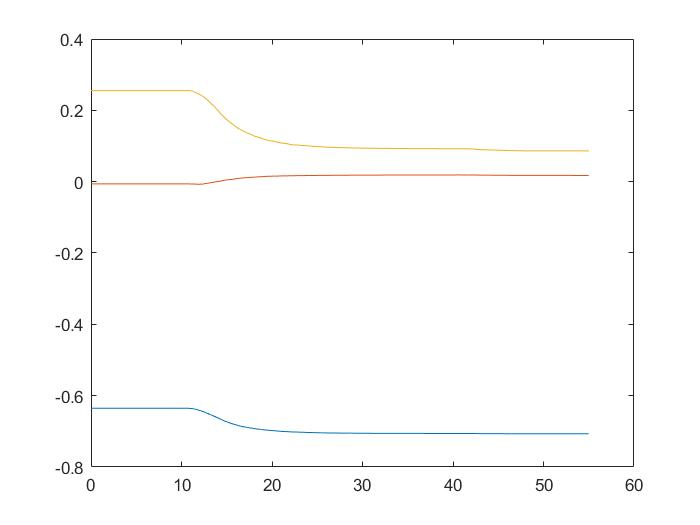


plot(time,robot_positions)

bag = rosbag('Tests_9.10\pt 9\pose_normal_pt_9_2.bag');

bSel = select(bag,'Topic','/tf_array_out');
% 
msgStructs = readMessages(bSel,'DataFormat','struct');
x = cellfun(@(m) double(m.Poses.Position.X),msgStructs);
y = cellfun(@(m) double(m.Poses.Position.Y),msgStructs);
z = cellfun(@(m) double(m.Poses.Position.Z),msgStructs);

position_cloud = [x y z]

position_cloud =    -0.7042    0.0215    0.0863
   -0.7042    0.0215    0.0863
   -0.7041    0.0218    0.0863
   -0.7041    0.0218    0.0863
   -0.7041    0.0218    0.0863
   -0.7042    0.0215    0.0863
   -0.7045    0.0215    0.0863
   -0.7045    0.0215    0.0863
   -0.7041    0.0218    0.0863
   -0.7041    0.0218    0.0863


mean_pos_cloud = mean(position_cloud)

mean_pos_cloud =    -0.7044    0.0217    0.0864



x = cellfun(@(m) double(m.Poses.Orientation.X),msgStructs);
y = cellfun(@(m) double(m.Poses.Orientation.Y),msgStructs);
z = cellfun(@(m) double(m.Poses.Orientation.Z),msgStructs);
w = cellfun(@(m) double(m.Poses.Orientation.W),msgStructs);
quaternion = [w,x , y, z]

quaternion =     0.0057    0.7244    0.6893    0.0109
    0.0045    0.7244    0.6893    0.0136
    0.0082    0.7243    0.6893    0.0138
    0.0096    0.7243    0.6892    0.0165
    0.0078    0.7243    0.6892    0.0185
    0.0082    0.7242    0.6892    0.0207
    0.0131    0.7241    0.6892    0.0227
    0.0070    0.7243    0.6892    0.0184
    0.0117    0.7242    0.6892    0.0214
    0.0110    0.7243    0.6892    0.0169


mean_quat = mean(quaternion)

mean_quat =     0.0108    0.7242    0.6892    0.0200


orientation_rpy = quat2eul(quaternion,'ZYX')*180/pi

orientation_rpy =    87.1623   -0.4481  178.6667
   87.1668   -0.7736  178.5486
   87.1668   -0.4996  178.2323
   87.1716   -0.6130  177.8988
   87.1767   -0.9189  177.8963
   87.1820   -1.0747  177.6830
   87.1848   -0.8511  177.1215
   87.1765   -0.9762  177.9606
   87.1822   -0.8568  177.3382
   87.1714   -0.5350  177.7533


mean_rpy = mean(orientation_rpy)

mean_rpy =    87.1775   -0.8034  177.5262


clf
error_position = abs(robot_positions - mean_pos_cloud)

error_position =     0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687
    0.0691    0.0279    0.1687


error_orientation = abs(robot_orientation_euler_deg -mean_rpy)

error_orientation =     1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823
    1.9875    0.2328    1.1823


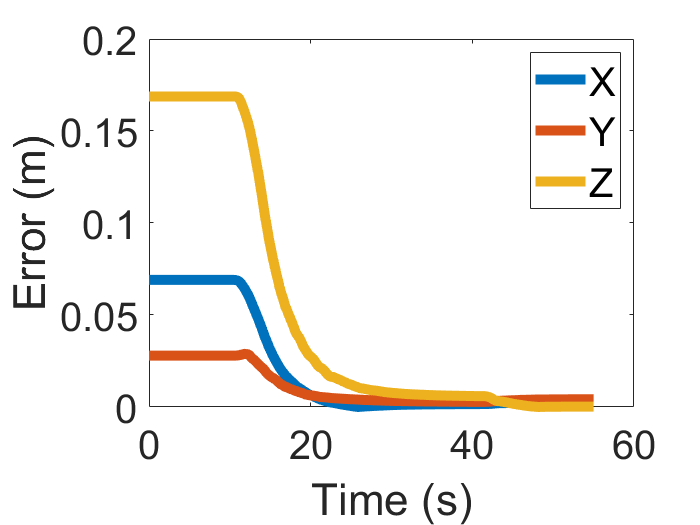


plot(time, error_position,'LineWidth',6)
ax = gca; 
ylabel("Error (m)",'FontSize',36)
xlabel("Time (s)",'FontSize',36)
legend(["X","Y","Z"],'FontSize',24)
ax.XAxis.FontSize = 24;
ax.YAxis.FontSize = 24;

% ylim([0 0.03])

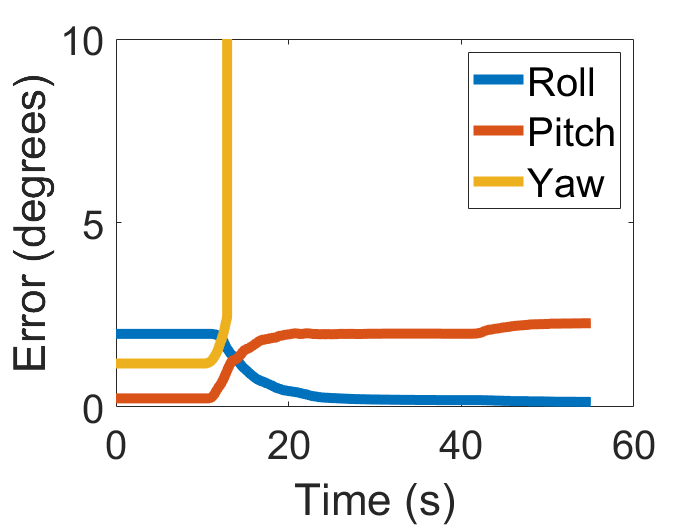

plot(time, error_orientation,'LineWidth',6)
ax = gca; 
ylabel("Error (degrees)",'FontSize',36)
xlabel("Time (s)",'FontSize',36)
ax.XAxis.FontSize = 24;
ax.YAxis.FontSize = 24;
legend(["Roll", "Pitch", "Yaw"],'FontSize',24)
ylim([0,10])
title("")